
$$y=c_1 \cdot e^{c_2 \cdot x} \;\Longrightarrow \;\ln \left(y\right)=\ln \left(c_1 \right)+\ln \left(e^{{c_2 \cdot x}_{\;} } \right)=\ln \left(c_1 \right)+c_2 \cdot x$$



$$\bar{c_{\;} } ={\left(A^T A\right)}^{-1} \cdot A^T \cdot \bar{b}$$


A = [1,1; 1,2; 1,4; 1,5]

A =      1     1
     1     2
     1     4
     1     5


y = [1;4;5;7];
b = log(y)

b =          0
    1.3863
    1.6094
    1.9459


c = ((A'*A)^-1)*A'*b;
c(1) = exp(c(1))

c =     1.0009
    0.4115


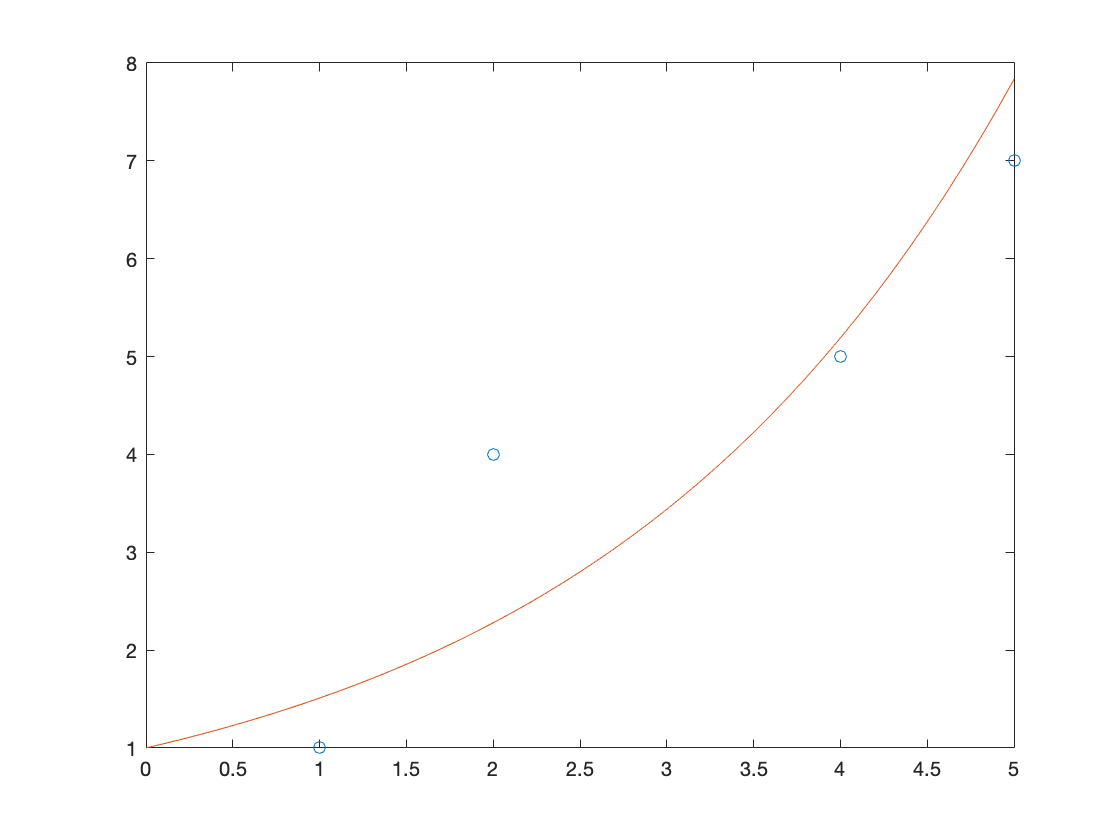

x = 0:0.1:5;
f = @(x) c(1)*exp(c(2)*x);
plot(A(:,2), y, "o")
hold on 
plot(x, f(x))
hold off